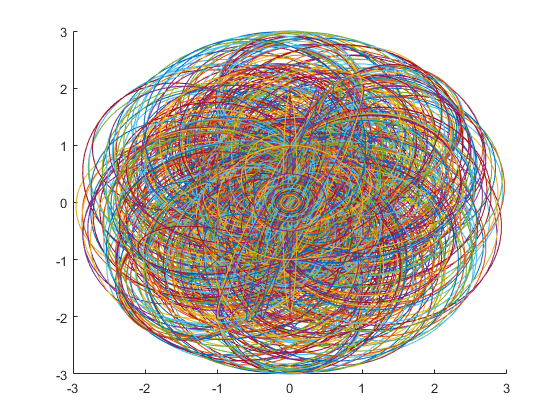

x=linspace(0,2,1000);
y=humps(x);
funx = @(x) humps(x);
%fimplicit(funx,linspace(0,2,100));
%plot(x,humps(x))
hold on
[y0,x_i]=max(y);
%plot(x(x_i),y0,'.','color','r','Markersize', 20)
%plot(x(y>=20 & y<=40),y(y>=20 & y<=40),'.')
a=0;
b=0;
t=linspace(-5,5,1000);
m=1;
n=12;
x1=@(t) (cos(t)-a.*cos(m*t)+b.*sin(n*t));
y1=@(t) (sin(t)+a.*sin(m*t)+b.*cos(n*t));

x_=x1(t);
y_=y1(t);
for k=1:10
    plot(x_/k,y_/k)
end